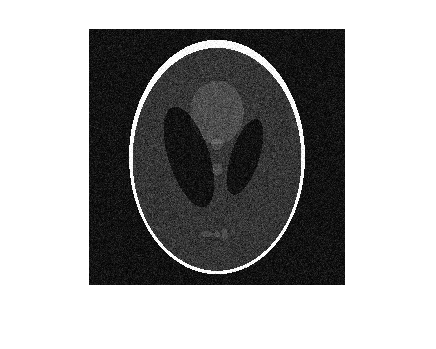

load("assignmentImageDenoisingPhantom.mat");
imshow(imageNoisy)

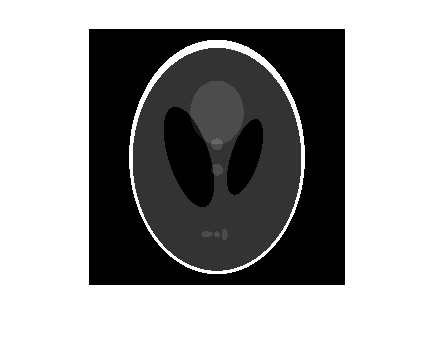

imshow(imageNoiseless)



mean = imageNoisy;
alpha = 0.9999999;
gamma = 0.008;

shift = zeros(256,256);
curr_image = imageNoisy;
iter = 0;
objective_values=zeros(100);
rms(rms(curr_image - imageNoiseless))/rms(rms(imageNoiseless))

ans = 0.2986

while true
    iter = iter + 1;
    iter
    temp_image = curr_image;
    for i = 1:256
        for j = 1:256
    
            shift_1 = circshift(curr_image,1,1)-curr_image;
            shift_2 = circshift(curr_image,-1,1)-curr_image;
            shift_3 = circshift(curr_image,1,2)-curr_image;
            shift_4 = circshift(curr_image,-1,2)-curr_image;            
            der_1 = -(1-alpha)*(curr_image(i,j)-mean(i,j));
            der_2 = 0.5*(alpha)*(deriv_DiscontinuityAdaptive(shift_1(i,j),gamma) + deriv_DiscontinuityAdaptive(shift_2(i,j),gamma)+ deriv_DiscontinuityAdaptive(shift_3(i,j),gamma) + deriv_DiscontinuityAdaptive(shift_4(i,j),gamma));
            shift(i,j) = 16*(der_1+der_2)/(20+iter);
        end
    end
    curr_image = curr_image + shift;
    rms(rms(curr_image - imageNoiseless))/rms(rms(imageNoiseless))
    
    obj=0;
    
    for i = 1:256
        for j = 1:256
            shift_1 = circshift(curr_image,1,1)-curr_image;
            shift_2 = circshift(curr_image,-1,1)-curr_image;
            shift_3 = circshift(curr_image,1,2)-curr_image;
            shift_4 = circshift(curr_image,-1,2)-curr_image;            
            term_1 = (1-alpha)*((curr_image(i,j)-mean(i,j))^2);
            term_2 = (alpha)*(DiscontinuityAdaptive(shift_1(i,j),gamma) + DiscontinuityAdaptive(shift_2(i,j),gamma)+ DiscontinuityAdaptive(shift_3(i,j),gamma) + DiscontinuityAdaptive(shift_4(i,j),gamma));
            obj=obj+term_1+term_2;
        end
    end
    
    objective_values(iter)=obj;
    
    if(rms(rms(shift))<0.001)
        break
    end
end

iter = 1

ans = 0.2846

iter = 2

ans = 0.2736

iter = 3

ans = 0.2650

iter = 4

ans = 0.2583

iter = 5

ans = 0.2532

iter = 6

ans = 0.2493

iter = 7

ans = 0.2463

iter = 8

ans = 0.2441

iter = 9

ans = 0.2424

iter = 10

ans = 0.2412

iter = 11

ans = 0.2402

iter = 12

ans = 0.2396

iter = 13

ans = 0.2391

iter = 14

ans = 0.2388

iter = 15

ans = 0.2386

iter = 16

ans = 0.2385

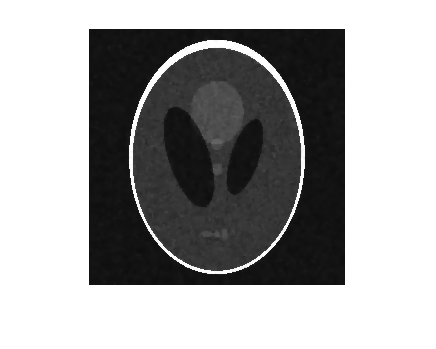

imshow(curr_image);

rms(rms(curr_image - imageNoiseless))/rms(rms(imageNoiseless))

ans = 0.2385

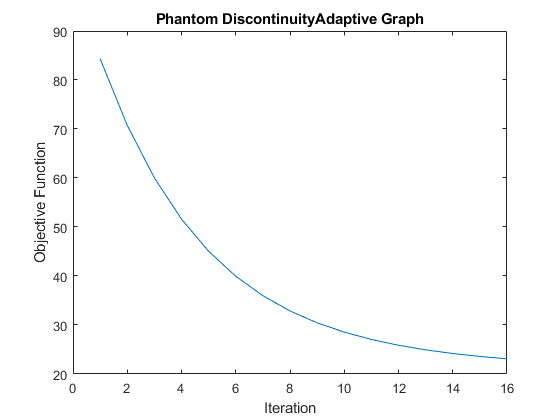

% Create indexed image, explicitly using 256 colors
imInd=gray2ind(curr_image,256);
% Convert indexed image to RGB using 256-colors jet map
jetRGB=ind2rgb(imInd,jet(256));
% Save image
imwrite(jetRGB,jet,'PhantomDiscontinuityAdaptive.png')

figure
plot(1:iter,objective_values(1:iter))
title('Phantom DiscontinuityAdaptive Graph')
xlabel('Iteration')
ylabel('Objective Function')
saveas(gcf,'Phantom DiscontinuityAdaptive Graph.png')

function [derivative] = deriv_DiscontinuityAdaptive(u,gamma)
%Outputs derivative of the Huber function
    modu=abs(u);
    derivative=u*gamma/(gamma+modu);
end

function [derivative] = deriv_Huber(u,gamma)
%Outputs derivative of the Huber function
    modu=abs(u);
    if(modu < gamma)
        derivative=u;
    else
        derivative=gamma*(u/modu);
    end
end

function [derivative] = deriv_quad(u,~)
%Outputs derivative of the Quadratic function
    derivative = 2*u;
end

function [value] = quad(u,~)
%quad function
    value=u^2;
end

function [value] = Huber(u,gamma)
%Huber function
    modu=abs(u);
    if(modu < gamma)
        value=0.5*u^2;
    else
        value=gamma*modu - 0.5*gamma^2;
    end
end

function [value] = DiscontinuityAdaptive(u,gamma)
%Discontinuity Adaptive function
    modu=abs(u);
    value=gamma*modu - (gamma^2)*log(1+(modu/gamma));
end